# Ejercicio 4 (2.5 puntos). 

### El exoesqueleto robótico REFLEX es un dispositivo de rehabilitación de rodilla basado en un motor de corriente continua. Dicho motor se comporta de manera que su señal de control, 𝑢(𝑡), comanda la velocidad de giro del eje, 𝑣(𝑡), según la relación $u\left(t\right)=\dot{v} \left(t\right)+15v\left(t\right)$.

### Se quiere controlar la posición del eje de dicho motor 𝑝(𝑡) para que siga comandos de posición angular. Para ello, se utiliza un esquema de control en lazo cerrado realimentando la posición angular del eje. Esta realimentación se realiza mediante un sensor que incorpora un filtro paso bajo correspondiente a la siguiente función de transferencia:

### 
$$H\left(s\right)=\frac{1}{0\ldotp 001s^2 +0\ldotp 05s+1}$$


- Utilizando Simulink, modele el sistema a controlar y esboce el diagrama de que representa el control de dicha articulación para el seguimiento de referencias posición (0.5 ptos)

En el modelo de simulink se tendra disponible los tres modelos, uno sin controlador, otro con el controlador de la parte b) y otro con el de la parte c).

H = tf(1,[0.001 0.05 1])

H =
 
            1
  ----------------------
  0.001 s^2 + 0.05 s + 1
 
Continuous-time transfer function.
Model Properties


Mot = tf(1, [1 15])

Mot =
 
    1
  ------
  s + 15
 
Continuous-time transfer function.
Model Properties


% Como hay que saber la posicion, la integral de la velocidad es la
% posicion
Int = tf(1,[1 0])

Int =
 
  1
  -
  s
 
Continuous-time transfer function.
Model Properties


G = Mot*Int

G =
 
      1
  ----------
  s^2 + 15 s
 
Continuous-time transfer function.
Model Properties


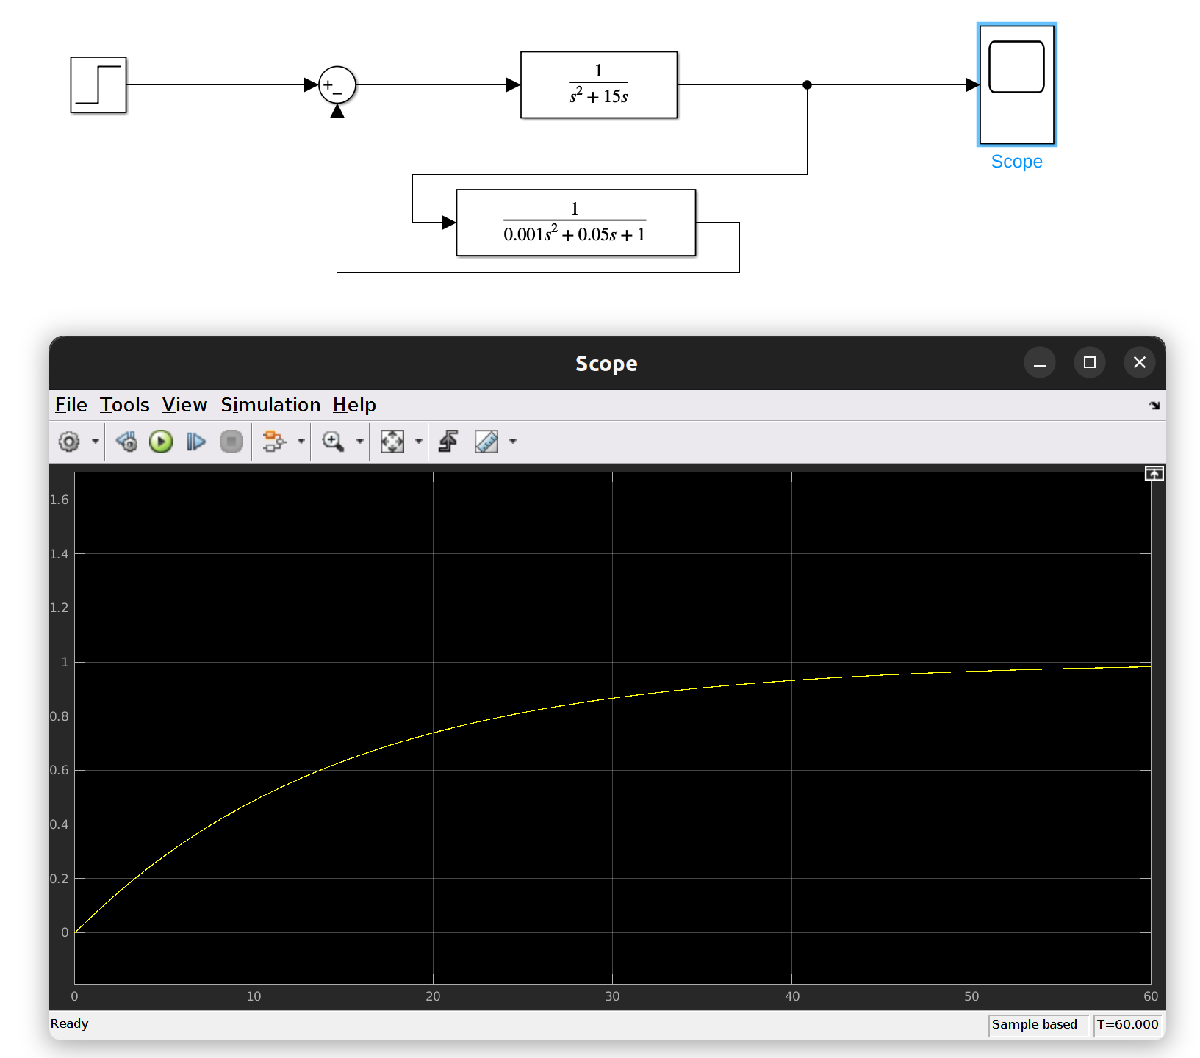

- Utilizando el método de Ziegler-Nichols de sintonización empírica de PIDs, el controlador PID para el sistema (1 pto).

Buscamos la ganancia necesaria para que el sistema oscile con rlocus y rlocfind.

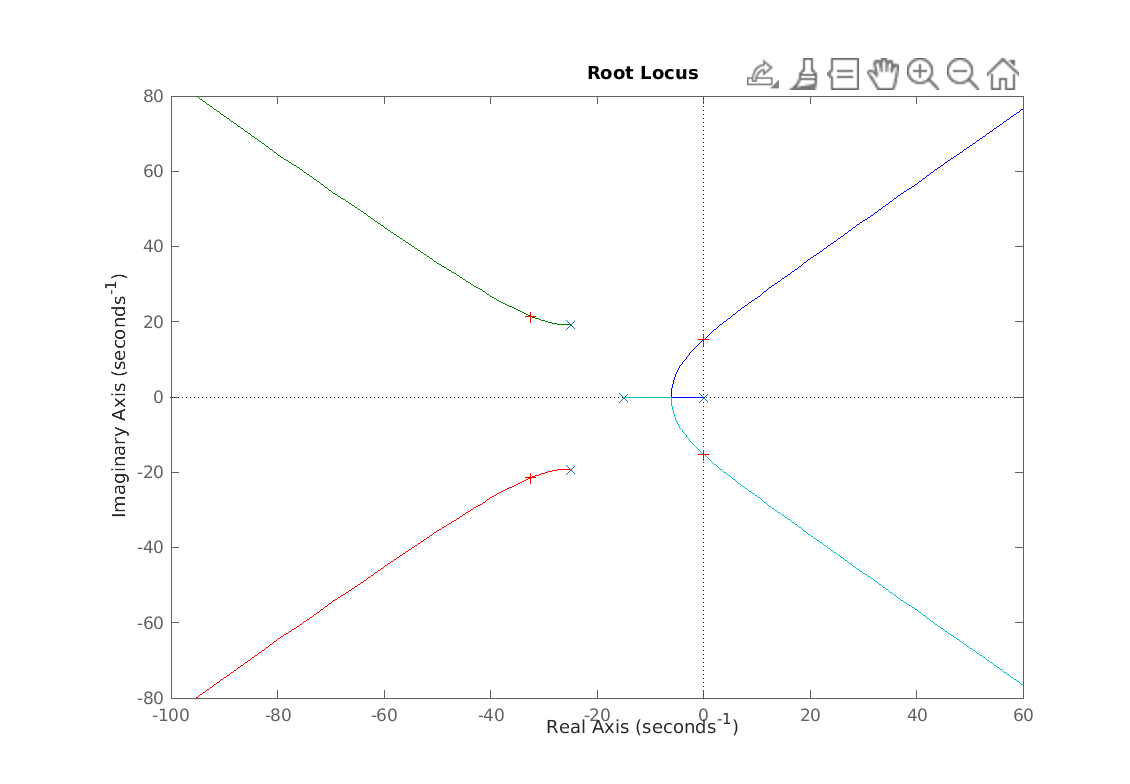

Select a point in the graphics window


selected_point = -0.1878 +15.2824i

Kcr = 348.5654

rlocus(G*H)
Kcr = rlocfind(G*H) % Aprox 350

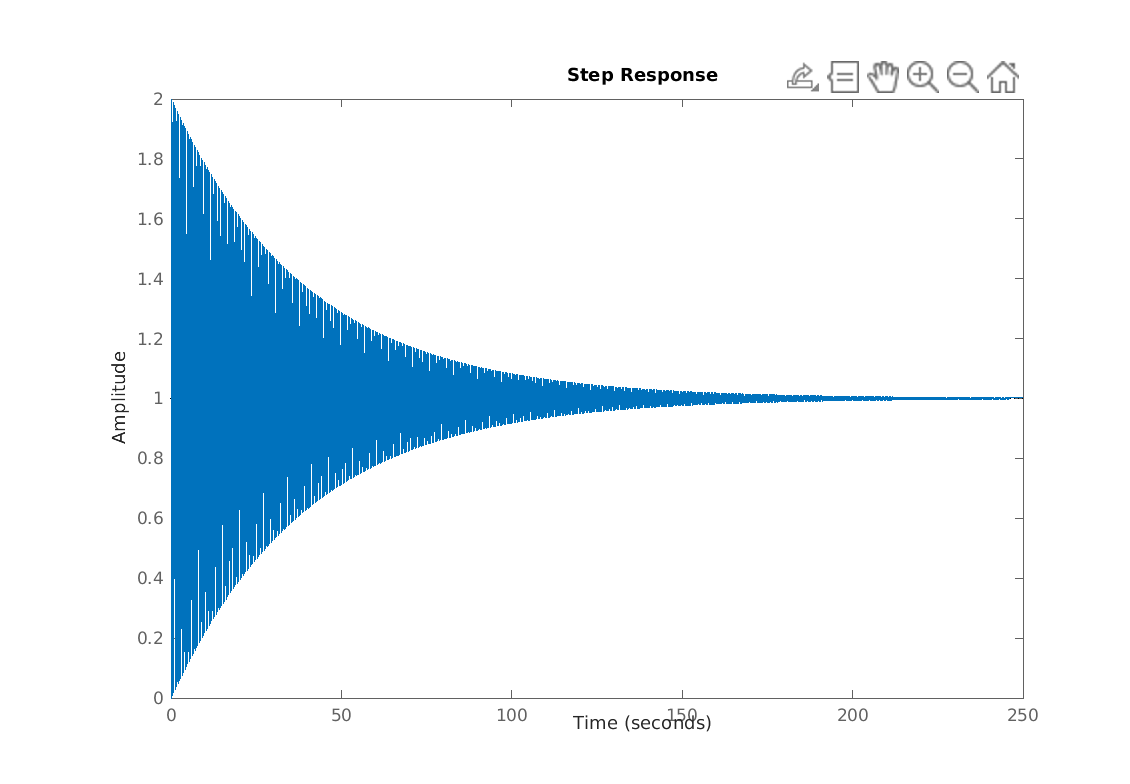


step(feedback(Kcr*G,H))

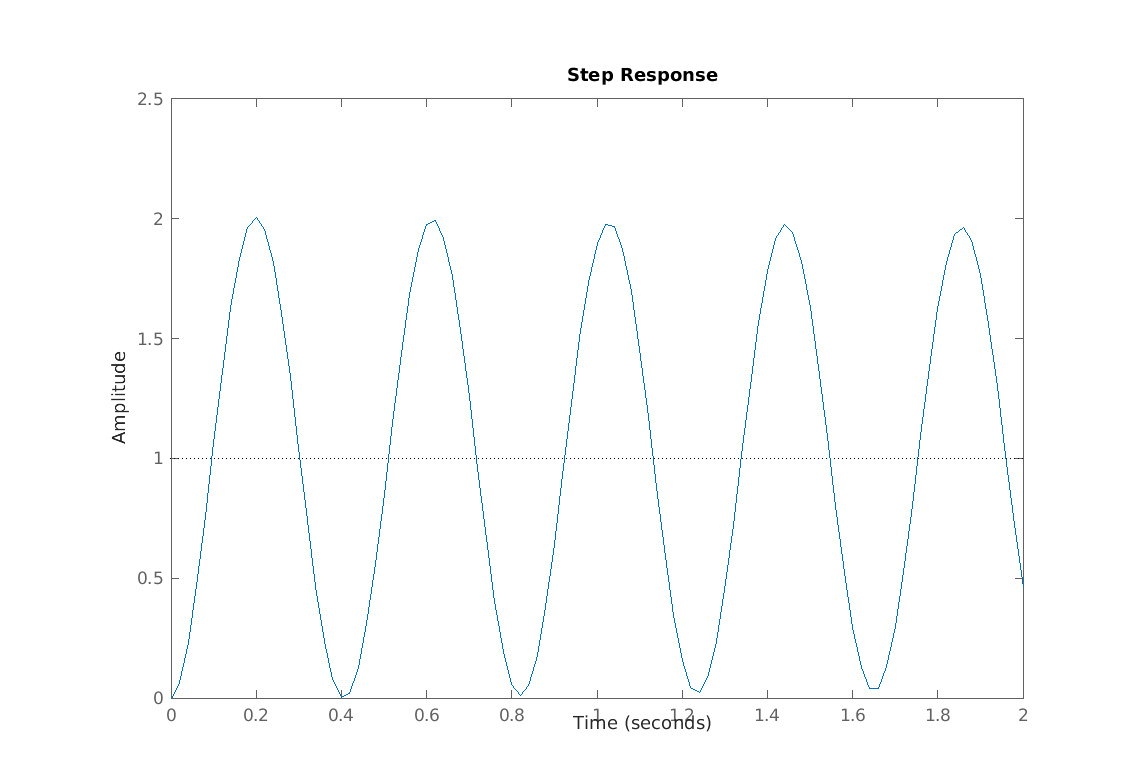

step(feedback(Kcr*G,H),2) % Para observar el periodo

Ahora observo en esta respuesta el periodo critico:

Pcr = 1.023 - 0.62

Pcr = 0.4030

Luego el PID resultante es:

Kp = 0.6*Kcr

Kp = 209.1392

Ti = 0.5*Pcr

Ti = 0.2015

Td = 0.125*Pcr

Td = 0.0504


s = tf('s');
PID_zn = Kp*((1 + Ti*s + Ti*Td*s*s)/(Ti*s))

PID_zn =
 
  2.123 s^2 + 42.14 s + 209.1
  ---------------------------
           0.2015 s
 
Continuous-time transfer function.
Model Properties


En esta imagen se puede ver la respuesta que tendra con este PID.

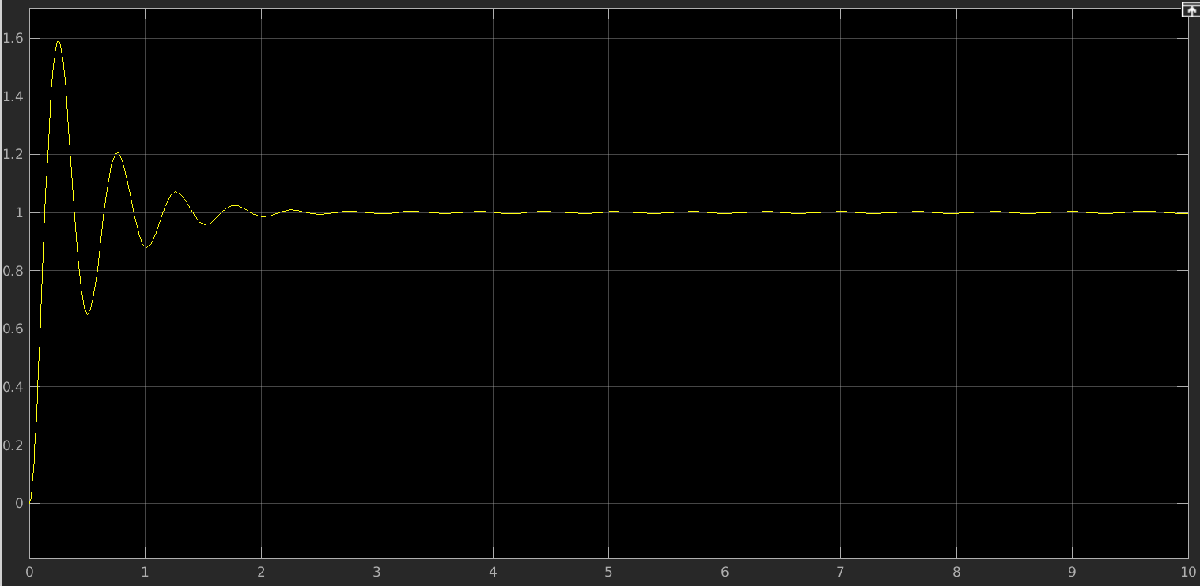

En el fichero de simulink ej4.slx tambien se incluye este controlador para que se pueda probar si se desea.

- Dentro del modelo simulink, introduce un controlador PID (bloque PID Controller) y explora las herramientas de sintonización automática de PIDs. Propón un controlador justificando sus prestaciones en el marco de la aplicación planteada (0.5 ptos)

En esta imagen se puede ver el uso de ls herramientas de sintonizacion automaticas de PID, y el PID resultante de usarlas.

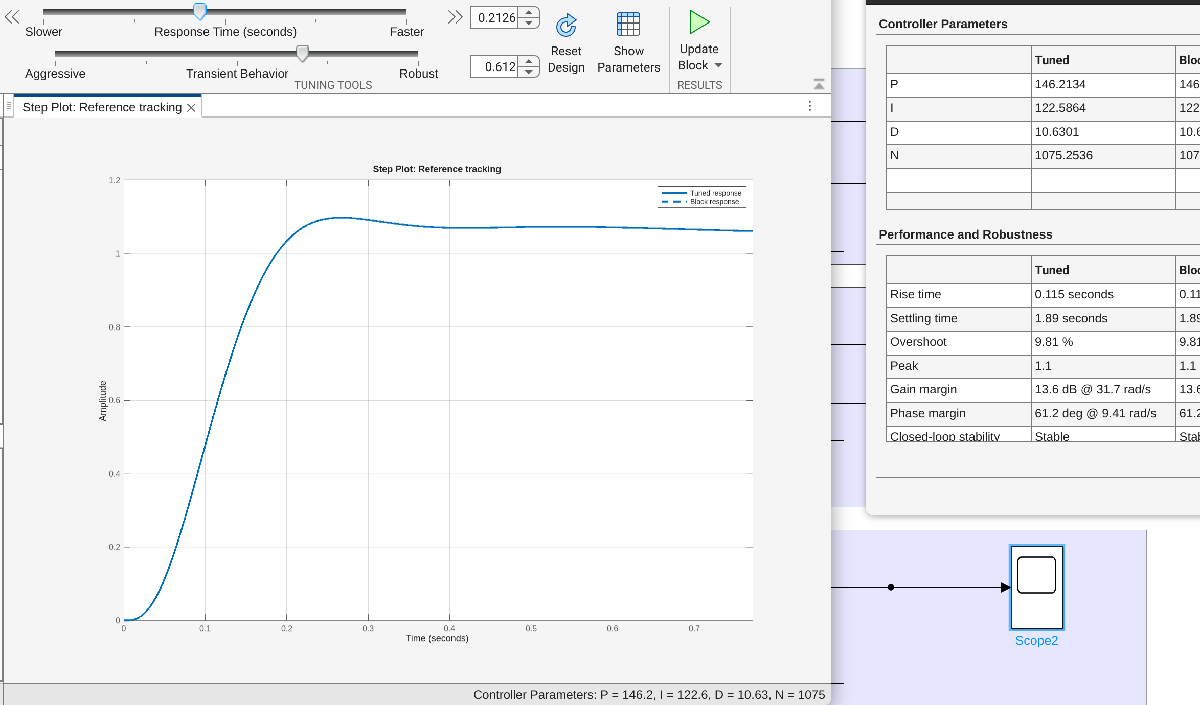

Y aqui se puede ver la respuesta del sistema con este PID:

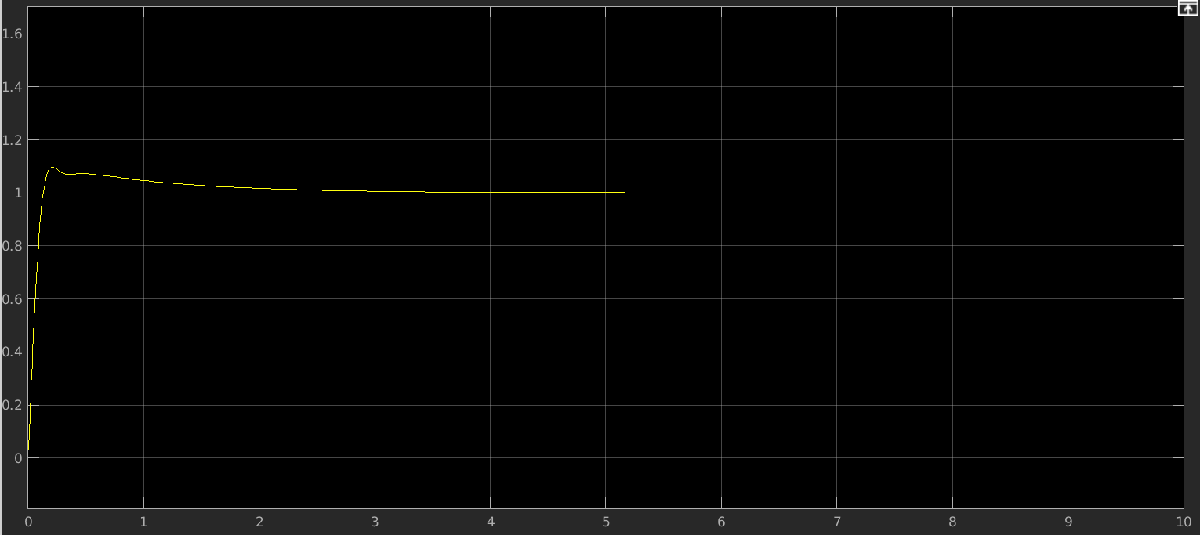

Se puede observar con facilidad que las respuestas del sistema con ambos controladores tienen un tiempo de asentamiento parecidos, en torno a 1.80 - 1.90 segundos. Tambien ocurre algo similar con el tiempo de subida y de pico, pero las mayores diferencias se encuentran en las oscilaciones del sistema.

El metodo de Ziegler-Nichols crea unas oscilaciones mucho mayores, tanto positivas como negativas, mientras que este segundo controlador presenta una leve oscilacion positiva. Como este sistema se encuentra en una protesis de rodilla es inconveniente que haya unas oscilaciones tan claras en la posicion, lo que podria causar el malestar del paciente o algun daño al mismo.

Por lo tanto, aunque ambos controladores se comporten de forma muy similar en el espacio temporal, el exceso de oscilaciones hace que el controlador mas deseado sea el ultimo creado.